# Składanie chmur punktów - zadanie

## Przygotowanie zbioru danych

dif_left = imageDatastore('auto_dif/left');
dif_right = imageDatastore('auto_dif/right');

pat_left = imageDatastore('auto_pat/left');
pat_right = imageDatastore('auto_pat/right');

load stereoParams.mat

disparityMaps = {};
clouds = {};
xyzs = {};
clouds = {};
keypoints = {};
feats = {};
locs = {};

% Parametry algorytmu stereo
disparityRange = [64, 400];

% Inicializacja potrzebnych zmiennych
Ip1 = readimage(pat_left, 1);
Ip2 = readimage(pat_right, 1);
[~, ~, reprojectionMatrix] = rectifyStereoImages(Ip1, Ip2, stereoParams, 'OutputView','full');

for id = 1:12
    Ip1 = readimage(pat_left, id);
    Ip2 = readimage(pat_right, id);
    Id1 = readimage(dif_left, id);
    Id2 = readimage(dif_right, id);
    
    [J1, J2, reprojectionMatrix] = rectifyStereoImages(Ip1, Ip2, stereoParams, 'OutputView','full');
    [C1, C2] = rectifyStereoImages(Id1, Id2, stereoParams, 'OutputView','full');

    % Zapamiętaj lewe zdjęcie kolorowe (bez wzorca)
    colors{id} = C1;

    % Wyznaczenie disparityMap na podstawie obrazów z rzutowanym wzorcem
    disparityMap = disparityBM(im2gray(J1), im2gray(J2), "DisparityRange", disparityRange, "BlockSize", 15, "UniquenessThreshold", 15, "TextureThreshold", 0.0002);
    disparityFiltered = filterDisparity(disparityMap, disparityRange);
    disparityMaps{id} = disparityFiltered;

    % Rekonstrukcja sceny 3D
    xyz = reconstructScene(disparityFiltered, reprojectionMatrix);

    xyzs{id} = xyz;
    clouds{id} = filterCloud(pointCloud(xyz, "Color", C1));

    % Wyznaczenie punktów charakterystycznych i ich filtracja (odrzucenie
    % punktów, dla których nie ma wyznaczonej pozycji 3D)
    kpoints = detectSURFFeatures(im2gray(C1), 'MetricThreshold', 100);
    [f, vpts] = extractFeatures(im2gray(C1), kpoints);

    keypointsMask = zeros(size(vpts));
    tmpLocs = zeros(size(vpts, 1), 3);

    for k = 1:length(vpts.Location)
        x = round(vpts.Location(k, 1));
        y = round(vpts.Location(k, 2));

        if disparityFiltered(y, x) < 400
            keypointsMask(k) = 1;
            tmpLocs(k, :) = xyz(y, x, :);
        end
    end

    keypoints{id} = vpts(keypointsMask == 1);
    locs{id} = tmpLocs(keypointsMask == 1, :);
    feats{id} = f(keypointsMask == 1, :);
end

## Wyznaczenie przekształceń pomiędzy kolejnymi parami widoków

matches = {};
tforms = {};
tclouds = clouds;

tforms{1} = rigidtform3d([-113, 0.3, 0], [0, 0, 343]);
tclouds{1} = pctransform(clouds{1}, tforms{1});

for id = 1:11
    matches{id} = matchFeatures(feats{id}, feats{id+1}, 'MaxRatio', 0.7, "MatchThreshold", 40.0, "Unique", true);

    locs1 = locs{id}(matches{id}(:,1), :);
    locs2 = locs{id+1}(matches{id}(:,2), :);
    tform = estgeotform3d(locs2, locs1, "rigid", "MaxDistance", 10);
    %tform2 = pcregistericp(clouds{id+1}, clouds{id}, "Metric", "pointToPoint", "InitialTransform", tform, "Verbose", false, "MaxIterations", 15, "InlierDistance", 30);
    tform2 = tform;
    tforms{id+1} = tform2;
    
    for k = 1:id+1
        tclouds{id+1} = pctransform(tclouds{id+1}, tforms{id + 1 - k + 1});
    end

end

## Wizualizacja wyrównanych chmur

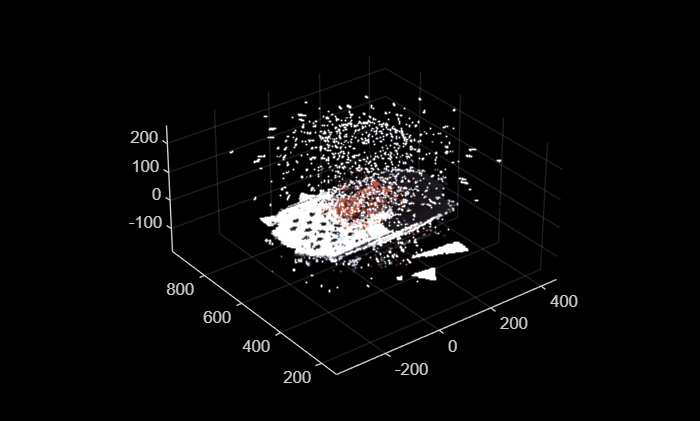

figure;
for id = 1:12
    pcshow(tclouds{id});
    hold on;
end

## Łączenie danych

merged = tclouds{1};

for k = 2:12
    merged = pcmerge(merged, tclouds{k}, 1);
end

## Wybór największego segmentu

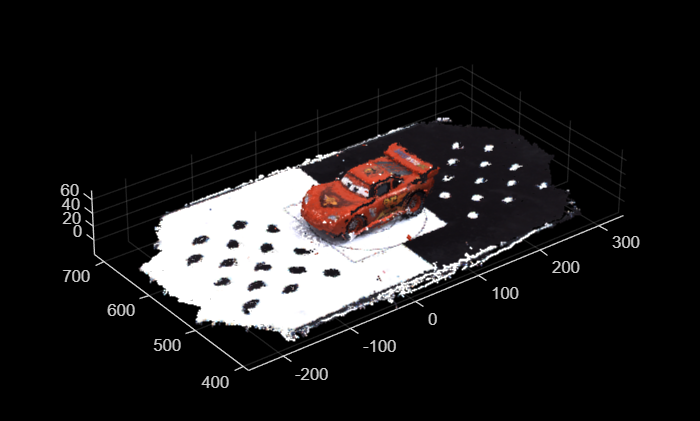

[labels, numClusters] = pcsegdist(merged, 3);
figure;
biggest = select(merged, find(labels == mode(labels)));
pcshow(biggest);

## Funkcje pomocniczne

function disparityFiltered = filterDisparity(disparityMap, disparityRange)
    disparityFiltered = disparityMap;
    disparityFiltered(disparityFiltered < 240) = NaN;
end

function cloudFiltered = filterCloud(cloud)
    cloudFiltered = cloud;
end